# Santos Port Throughput Analysis

## Overview

## Objective

This project aims to analyze the time series of container cargo throughput at the Port of Santos to uncover trends, seasonality, and patterns in port activity. By focusing on containerized cargo, the analysis provides insights into the dynamics of the Brazil's most important trade hub.

Key steps in the project include:

- **Data Load and Preparation**: Loading and filtering the dataset to include only data related to conteiner activity.

- **Exploratory Data Analysis**: Visualizing throughput over time, identifying trends, seasonal variations, and potential anomalies.

- **Time Series Modeling**: Developing predictive models to forecast container throughput and evaluate performance against historical data.

- **Insights and Implications**: Generating actionable insights into port activity to support decision-making.

## Import and Preprocessing the data

clear
close
clc
format shortG

data = import_aps_data;

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.


head(data)

      Ano        Mês         DESC_SIMPLES        TIPO_INSTALAÇÃO (grupos)       Terminal - GERIN          naturezacarga        TIPO_MOVIMENTO        navegacao        Sentido_carga         desc_spa         Toneladas    TEUs    Unidades
    ________    _____    ____________________    ________________________    _______________________    __________________    ________________    _______________    _______________    _________________    _________    ____    ________

    {'2024'}    {'1'}    {'I. BARNABE OESTE'}      {'PORTO ORGANIZADO'}      {'AGEO'   

% Visualize the variable names and type and the number of observations
[data.Properties.VariableNames; data.Properties.VariableTypes]'

ans = 13×2 string array
    "Ano"                         "cell"  
    "Mês"                         "cell"  
    "DESC_SIMPLES"                "cell"  
    "TIPO_INSTALAÇÃO (grupos)"    "cell"  
    "Terminal - GERIN"            "cell"  
    "naturezacarga"               "cell"  
    "TIPO_MOVIMENTO"              "cell"  
    "navegacao"                   "cell"  
    "Sentido_carga"               "cell"  
    "desc_spa"                    "cell"  
    "Toneladas"                   "double"
    "TEUs"                        "double"
    "Unidades"                    "double"


no_of_observations = height(data)

no_of_observations =       283220


The dataset contains over 280,000 observations and 13 columns, including details such as year, month, terminal, cargo type, units, weight, TEUs, and more.

Let's examine the types of cargo represented in the dataset by identifying the unique values in the `naturezadacarga ``column:`

types_of_cargo = unique(data.naturezacarga)

types_of_cargo = 5×1 cell array
    {0×0 char              }
    {'CARGA CONTEINERIZADA'}
    {'CARGA GERAL'         }
    {'GRANEL LIQUIDO'      }
    {'GRANEL SOLIDO'       }


The analysis focuses specifically on container cargo, so I will filter the dataset to include only rows where the `naturezadacarga` column indicates **CARGA CONTEINERIZADA**. This step excludes all other cargo types, such as bulk or general cargo.

container_data = data(data.naturezacarga == "CARGA CONTEINERIZADA",:);

Next, we need to summarize the data by year and month, create a time variable, and set this variable as the time index in our timetable.

% Summarizes the container data by year ("Ano") and month ("Mês")
monthly_data = groupsummary(container_data,["Ano","Mês"],"sum","TEUs");
monthly_data = renamevars(monthly_data,"sum_TEUs","TEUs")

monthly_data = 238×4 table
      Ano        Mês      GroupCount       TEUs   
    ________    ______    __________    __________

    {'2005'}    {'1' }       904         1.686e+05
    {'2005'}    {'10'}       917        2.0546e+05
    {'2005'}    {'11'}       818        1.7695e+05
    {'2005'}    {'12'}       797        1.8934e+05
    {'2005'}    {'2' }       904        1.5497e+05
    {'2005'}    {'3' }       923        1.8672e+05
    {'2005'}    {'4' }       865        1.7257e+05
    {'2005'}    {'5' }       901        2.0218e+05
    {'2005'}    {'6' }       852        1.9235e+05
    {'2005'}    {'7' }       828        2.0301e+05
    {'2005'}    {'8' }       917        2.0998e+05
    {'2005'}    {'9' }       867        1.9816e+05
    {'2006'}    {'1' }       880        1.6578e+05
    {'2006'}    {'10'}       923        2.3149e+05
    {'2006'}    {'11


% Create date variable from year and month columns
dates = datetime(str2double(monthly_data.Ano), str2double(monthly_data.("Mês")), 1);

% Create a timetable using dates as time indexes
data_timetable = table2timetable(monthly_data, 'RowTimes', dates);

% Remove unnecessary variables
data_timetable.Ano = [];
data_timetable.("Mês") = [];
data_timetable.GroupCount = [];

% Sort data by Time
data_timetable = sortrows(data_timetable,"Time");

% Determine if input times are regular with respect to calendar unit (month)
[tf, dt] = isregular(data_timetable,"months")

tf = logical
   1


dt = calendarDuration
   1mo


The data is monthly and contain no missing months. The first and last dates are shown below:

data_timetable.Properties.StartTime

ans = datetime
   01-Jan-2005


data_timetable.Time(end)

ans = datetime
   01-Oct-2024


For this analysis, only data from the past 10 years (from 2014 to 2023) will be used, with data from 2024 reserved for model testing. Dates outside this range will be filtered out accordingly.

% Exclude data prior to 2014 and after 2023 for train
% trainData = data_timetable(isbetween(year(data_timetable.Time), 2014, 2023), :);
trainData = data_timetable((year(data_timetable.Time) < 2024), :);

% Reserving the 2024 data for testing
testData = data_timetable(year(data_timetable.Time) > 2023, :);

% Visualyze the first and last rows of the train data
head(trainData)

       Time           TEUs   
    ___________    __________

    01-Jan-2005     1.686e+05
    01-Feb-2005    1.5497e+05
    01-Mar-2005    1.8672e+05
    01-Apr-2005    1.7257e+05
    01-May-2005    2.0218e+05
    01-Jun-2005    1.9235e+05
    01-Jul-2005    2.0301e+05
    01-Aug-2005    2.0998e+05



tail(trainData)

       Time           TEUs   
    ___________    __________

    01-May-2023    4.0313e+05
    01-Jun-2023    3.8644e+05
    01-Jul-2023     4.217e+05
    01-Aug-2023    4.4884e+05
    01-Sep-2023    3.9754e+05
    01-Oct-2023    4.3975e+05
    01-Nov-2023    4.0958e+05
    01-Dec-2023    4.3408e+05



The data preprocessing has been completed, and the dataset is now prepared for further analysis and modeling.

## Exploratory Analysis

### Understanding Trend

To begin, a run sequence plot of the series is generated to observe the movement of TEU in Santos over time:

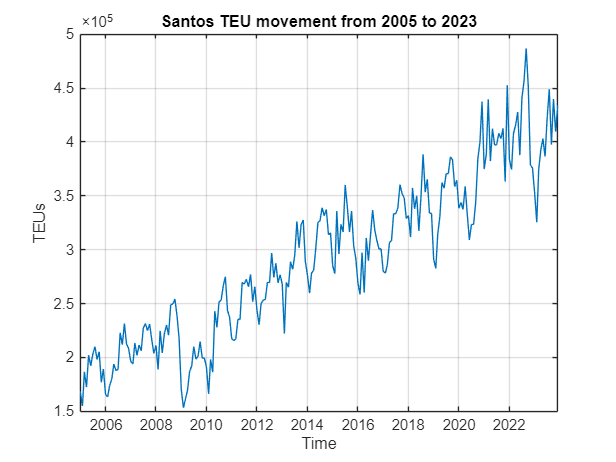

figure
plot(trainData,"Time","TEUs")
title("Santos TEU movement from 2005 to 2023")
grid on

The data indicate a trend due to the consistent upward movement over time. Despite the fluctuations, the total TEUs handled at Santos show a clear long-term increase from 2005 to 2023.

### Understanding Seasonality Patterns

The data possibly exhibit some seasonal pattern, with low activity at the beginning of the year and a peak in the second half. The boxplot below demonstrates how the number of TEUs is distributed across the months of the year.

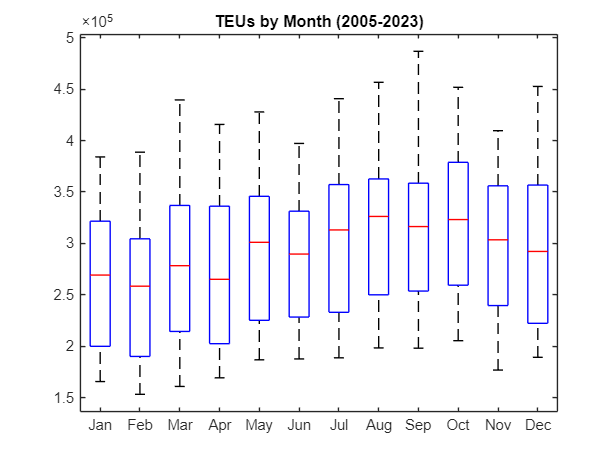

% Add a column with the month number
trainData.Month = month(datetime(string(trainData.Time)));

% Generate boxplot with the month labels
figure
month_labels = {'Jan', 'Feb', 'Mar', 'Apr', 'May', 'Jun', 'Jul', 'Aug', 'Sep', 'Oct', 'Nov', 'Dec'};
boxplot(trainData.TEUs,trainData.Month,"Labels",month_labels)
title("TEUs by Month (2005-2023)")

As expected, the beginning of the year shows a lower median volume, with the highest volumes concentrated in the second half. To illustrate this more clearly, let's generate another boxplot, this time highlighting the TEU variation across the quarters of the year.

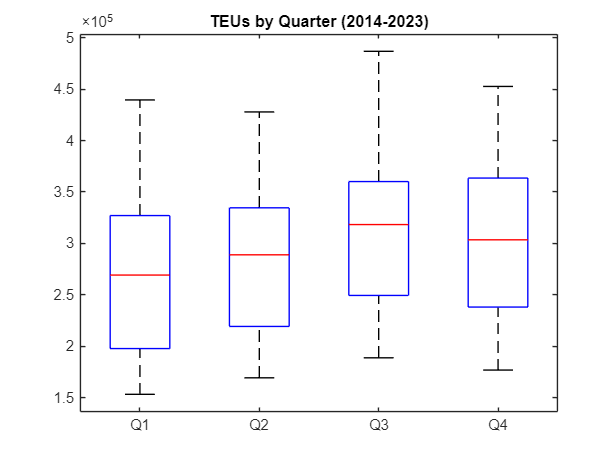

% Add a column with the quarter number
trainData.Quarter = quarter(datetime(string(trainData.Time)));

% Generate boxplot with the quarter labels
figure
quarter_labels = {'Q1', 'Q2', 'Q3', 'Q4'};
boxplot(trainData.TEUs,trainData.Quarter,"Labels",quarter_labels)
title("TEUs by Quarter (2014-2023)")

It is also possible to observe that there is not outlier in the data.

### Understanding Variability

In order to understand the variability, let's create a scatter plot of the yearly TEUs statistcs:

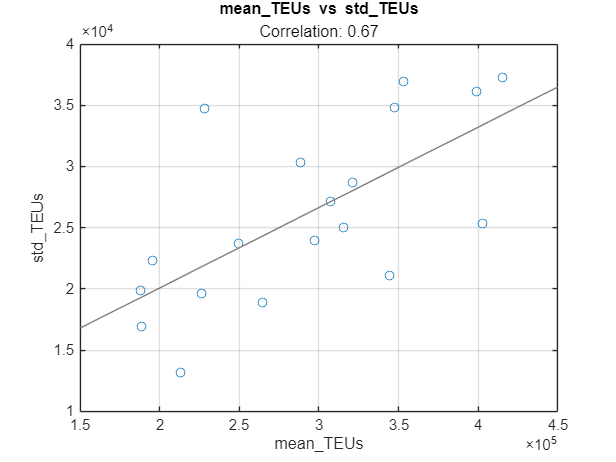

% Compute the statistic by year
yearlyData = groupsummary(trainData,"Time","year",["mean","std"],"TEUs");
yearlyData.GroupCount = [];

% Create the scatter plot
figure
scatter(yearlyData,"mean_TEUs","std_TEUs")
lsline
title("mean\_TEUs vs std\_TEUs",sprintf('Correlation: %.2f', corr(yearlyData.mean_TEUs,yearlyData.std_TEUs)))
box on
grid on

The positive correlation between the standard deviation and the mean suggests heteroscedasticity, meaning that the variability of the data changes over time.

Trends and changes in variability indicate non-stationarity in the time series, which can affect analysis and predictive models. To address this, it is necessary to transform the data appropriately. These transformations aim to stabilize the variance and bring the time series closer to stationarity. Additionally, it is important to decompose the time series to identify and separate the trend and periodicity components, allowing for more accurate data analysis.

All transformations performed will be reversed later to ensure accurate predictions and maintain interpretability.

## Data Transformation for Stationarity

To address the heteroscedasticity identified in the data, we will apply a logarithmic transformation, as there is a positive correlation between mean_TEUs and std_TEUs. 

trainData.logTEUs = log(trainData.TEUs);

% Compare the data range before and after the logarithmic transformation
originalRange = [min(trainData.TEUs), max(trainData.TEUs)]

originalRange =       153409      486756


transformedRange = [min(trainData.logTEUs), max(trainData.logTEUs)]

transformedRange =        11.941       13.096


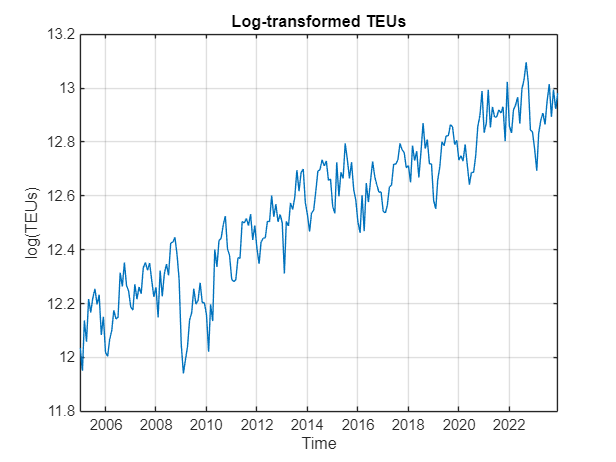

% Visualize the transformed data
figure;
plot(trainData.Time, trainData.logTEUs);
xlabel("Time");
ylabel("log(TEUs)");
title("Log-transformed TEUs");
grid on;

### Comparing the Statistical Properties

Let's visually compare the mean and standard deviation of the original and the transformed data. 

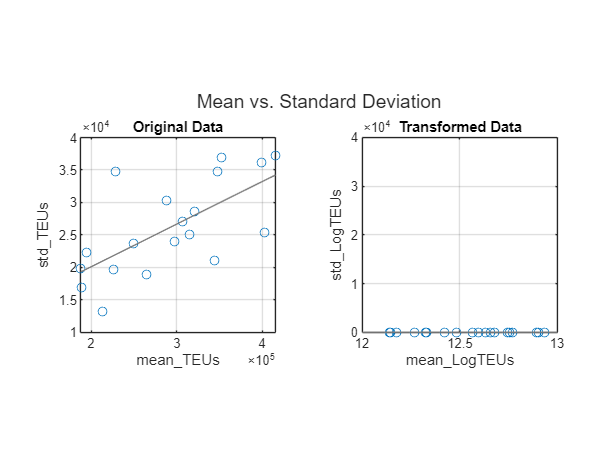

figure
t = tiledlayout(1,2);
nexttile
scatter(yearlyData,"mean_TEUs","std_TEUs");
xlabel("mean\_TEUs")
ylabel("std\_TEUs")
title("Original Data")
grid on
box on
axis square
lsline
yearlyLogData = groupsummary(trainData,"Time","year",["mean","std"],"logTEUs");
yearlyLogData.GroupCount = [];
nexttile
scatter(yearlyLogData,"mean_logTEUs","std_logTEUs");
xlabel("mean\_LogTEUs")
ylabel("std\_LogTEUs")
title("Transformed Data")
grid on
box on
axis square
ylim([0 4e4])
lsline
title(t,"Mean vs. Standard Deviation")

## Time Series Decomposition: Identifying Trends and Seasonality